# Sentiment Analysis: Calling Python from MATLAB

## Set up Python and Python path

pyversion


       version: '2.7'
    executable: '/usr/bin/python'
       library: 'libpython2.7.so.1.0'
          home: '/usr'
      isloaded: 0



pathToSpeech = fileparts(which('mySpeechRecognizer.py'));
if count(py.sys.path,pathToSpeech) == 0
    insert(py.sys.path,int32(0),pathToSpeech);
end

## Create audio recorder

sampleRate = 16000;
numChannels = 1;
rec = audiorecorder(sampleRate,8,numChannels);

## Get audio data from the microphone

disp('Hearing audio clip...')

Hearing audio clip...


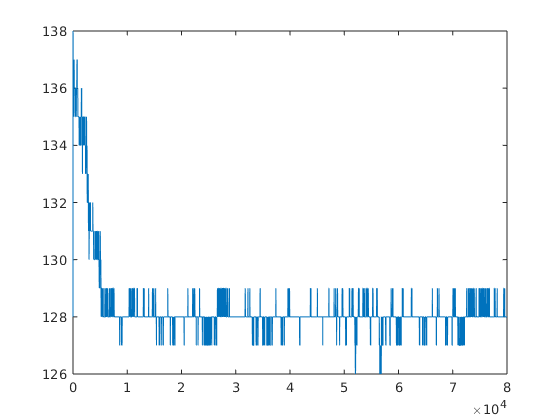

recordblocking(rec,5);
audioData = getaudiodata(rec,'uint8')';
plot(audioData);

## Call Python speech recognizer and convert outputs to MATLAB data types

pyOut = py.mySpeechRecognizer.audioToText(audioData,sampleRate,numChannels);

Unable to resolve the name py.mySpeechRecognizer.audioToText.

myText = string(pyOut{1});
successFlag = logical(pyOut{2});
disp(myText)

## Perform sentiment analysis

NOTE: If you are in a version older than R2019b, you can instead use the `sentimentAnalysisCustom` function.

[sentiment,scores] = sentimentAnalysisVADER(myText)

*Copyright 2019 The MathWorks, Inc.*